# Search images that are either spatially or temporally close images.

## Load the polygons of each image obtained by DDR data

load ddr_polygons_wutc.mat
load ddr_polygons_wutc.mat

## Specify the range of target IDs.

% Enter directory name: 3-letter observsation class type + zero padded 8 
% digit observation ID. The polygonal footprint of this image will be 
% shown in red in the map projection.
dirname_tar = 'FRT00009A16';

% Provide Time difference tolerance in days
tol_days = 7;

% Modify the following distance threshold value if you want to apply
% spatially close images.
% the images within the distance less than this value would be selected.
% Enter Inf if you want to skip this selection.
dst_threshold = inf;
% This distance in the map-projected coordinate system.
% For equirectangular projection, X axis is measured by longitude in
% degrees and Y axis is by latitude in degrees.
% For stereographic projection, sorry, not sure. 

% obs_class_type
% You can specify the type of observations you want to match.
% If none given, full resolution types (FRT, FRS, ATO) are selected for
% full resolution observations, and full and half resolution types (FRT,
% FRS, ATO, HRL, HRS) are selected for half resolution images.
obs_class_type_allowed = {};

% latitude range
% You can specify the range of the latitude of the candidate observations.
% if it is empty, images with latitude > 70deg for north polar images,
% latitude < -70 deg for south polar images, -70 < latitude < 70 otherwise.
% latitude_range = [60, 95];
latitude_range = [-70 70];


% Path to the MOLA image file
imgpath_mola = 'Mars_MGS_MOLA_DEM_mosaic_global_1024.jpg';
if ~exist(imgpath_mola, 'file')
    error('%s does not exist.', imgpath_mola);
end

% By default projection method is automatically selected. If the latitude
% of the center of the image is higher than 70 deg or lower than 70, 
% stereographic projection is selected. Otherwise (latitude is between -70 
% and 70 degs), equirectangular projection is selected.
idx_tar = find(strcmpi(dirname_tar, {ddr_polygons.dirname}));
if isempty(idx_tar)
    error('%s is not right.', dirname_tar);
end
polygon_tar = ddr_polygons(idx_tar);
lat_ctr_tar = polygon_tar.lat_ctr;
lon_ctr_tar = polygon_tar.lon_ctr;
if abs(lat_ctr_tar) > 70
    projection_method = 'stereographic';
    R = 1; % radius is one meter??
else
    projection_method = 'equirectangular';
end
% If you want to manually specify the type of projection, Uncomment below 
% and enter the projection type (case-insensitive)
% projection_method = 'equirectangular'; % 'stereographic'

## Apply time tolerance

tol_duration = calendarDuration(0,0,tol_days);
idx_slctd = find(and(polygon_tar.time - tol_duration < [ddr_polygons.time], ...
    [ddr_polygons.time] < polygon_tar.time + tol_duration));
ddr_polygons_slctd = ddr_polygons(idx_slctd);

% sort ddr_polygons_slctd by time
timestamps = [ddr_polygons_slctd.time];
[~, idx_srtt] = sort(timestamps);
ddr_polygons_slctd = ddr_polygons_slctd(idx_srtt);

## Apply observation class type filter

if isempty(obs_class_type_allowed)
    switch upper(dirname_tar(1:3))
        case {'FRT', 'FRS', 'ATO'}
            obs_class_type_allowed = {'FRT', 'FRS', 'ATO'};
        case {'HRL', 'HRS'}
            obs_class_type_allowed = {'HRL', 'HRS', 'FRT', 'FRS', 'ATO'};
            % obs_class_type_allowed = {'HRL', 'HRS'};
        otherwise
            error('Unsupported observation class type %s', dirname_tar(1:3));
    end
end
obs_class_type_ptrn = ['(' strjoin(obs_class_type_allowed,'|') ')'];

mtch = regexpi({ddr_polygons_slctd.dirname}, obs_class_type_ptrn);
idx_slctd = find(~isempties(mtch));
ddr_polygons_slctd = ddr_polygons_slctd(idx_slctd);

if isempty(latitude_range)
    switch upper(projection_method)
        case 'EQUIRECTANGULAR'
            latitude_range = [-70, 70];
        case 'STEREOGRAPHIC'
            if lat_ctr_tar > 0
                latitude_range = [70, inf];
            else
                latitude_range = [-inf, -70];
            end
    end
end

idx_slctd = find(and(latitude_range(1) < [ddr_polygons_slctd.lat_ctr], ...
    [ddr_polygons_slctd.lat_ctr] < latitude_range(2)));
ddr_polygons_slctd = ddr_polygons_slctd(idx_slctd);

## Project all the DDR polygons to the selected projection method.

lat_centers = [ddr_polygons_slctd.lat_ctr];
lon_centers = [ddr_polygons_slctd.lon_ctr];
switch upper(projection_method)
    case 'EQUIRECTANGULAR'
        X_tar = lon_ctr_tar;
        Y_tar = lat_ctr_tar;
        Y = lat_centers;
        X = lon_centers;
    case 'STEREOGRAPHIC'
        k = 2*R*cosd(lat_ctr_tar)./(1+sind(lat_ctr_tar));
        X_tar = k.*cosd(lon_ctr_tar);
        Y_tar = k.*sind(lon_ctr_tar);
        k = 2*R*cosd(lat_centers)./(1+sind(lat_centers));
        X = k.*cosd(lon_centers);
        Y = k.*sind(lon_centers);
end

## Apply distance-based screening if you want to.

dsts = sqrt((X-X_tar).^2+(Y-Y_tar).^2);
idx_close = dsts < dst_threshold;
ddr_polygons_slctd = ddr_polygons_slctd(idx_close);

## Load MOLA image and show it in the specified projection.

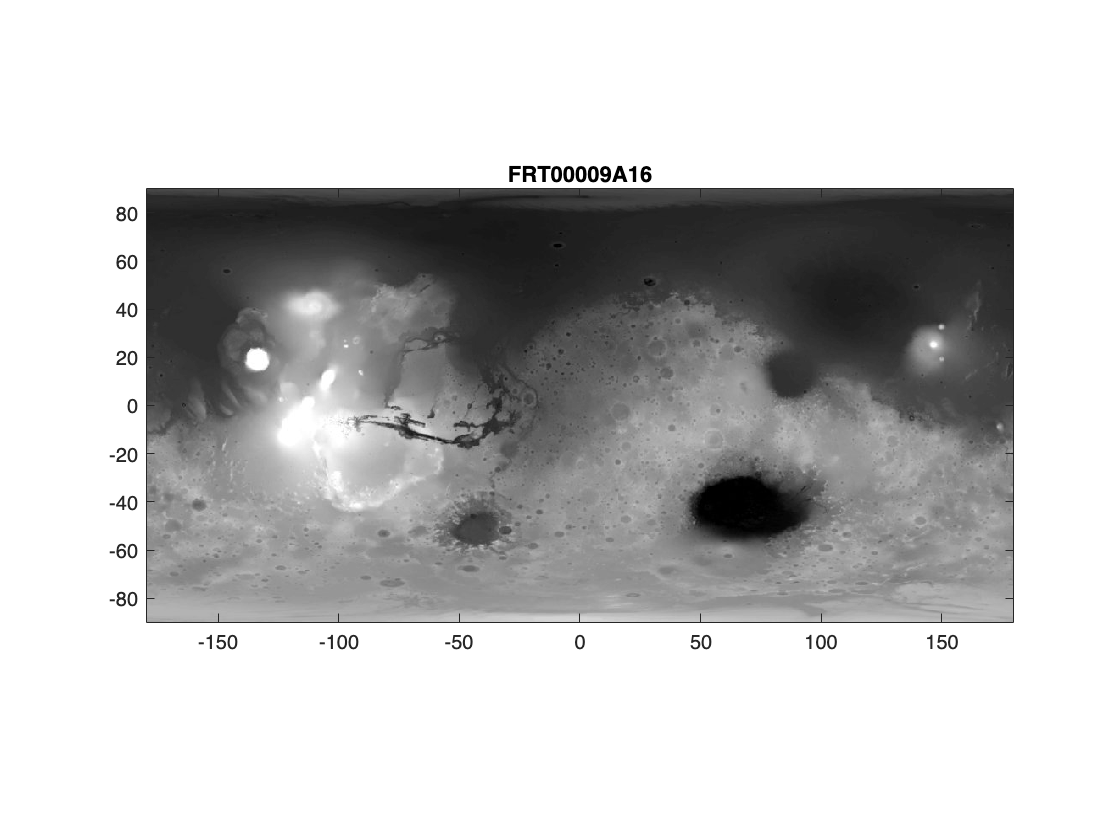

[img_mola] = imread(imgpath_mola);
lat_pitch = 180/size(img_mola,1);
lon_pitch = 360/size(img_mola,2);
fig = figure('Name', dirname_tar);
ax = subplot(1,1,1);
switch upper(projection_method)
    case 'EQUIRECTANGULAR'
        img_mola_latitude = (90-lat_pitch/2):(-lat_pitch):(-90);
        img_mola_longitude = (-180+lon_pitch/2):(lon_pitch):(180);
        Xmola = img_mola_longitude;
        Ymola = img_mola_latitude;
        imagesc(Xmola([1,end]),Ymola([1,end]),img_mola(:,:,1));
        colormap('gray');
        set(gca,'Ydir','normal');
    case 'STEREOGRAPHIC'
        img_mola_latitude = (90-lat_pitch/2):(-lat_pitch):(-90);
        img_mola_longitude = (-180+lon_pitch/2):(lon_pitch):(180+lon_pitch);
        if lat_ctr_tar > 60
            img_mola_p = cat(2,img_mola(img_mola_latitude>60,:,:),img_mola(img_mola_latitude>60,1,:));
            img_mola_lat_np = img_mola_latitude(img_mola_latitude>60);
            [lonmap,latmap] = meshgrid(img_mola_longitude,img_mola_lat_np);
        elseif lat_ctr_tar < -60
            img_mola_p = cat(2,img_mola(img_mola_latitude<-60,:,:),img_mola(img_mola_latitude<-60,1,:));
            img_mola_lat_sp = img_mola_latitude(img_mola_latitude<-60);
            [lonmap,latmap] = meshgrid(img_mola_longitude,img_mola_lat_sp);
        end
        R = 1;
        k = 2*R*cosd(latmap)./(1+sind(latmap));
        Xmola = k.*cosd(lonmap);
        Ymola = k.*sind(lonmap);
        Zmola = ones(size(Xmola));
        surf(ax, Xmola,Ymola,Zmola,img_mola_p(:,:,1),'EdgeColor','none');
        view(2);
        colormap('gray');
        hold on;
        grid_lat_list = [60, 70, 80];
        r = 2*R*cosd(grid_lat_list)./(1+sind(grid_lat_list));
        thetas = linspace(0,2*pi,361); % every 1 degree
        x = r' .* cos(thetas);
        y = r' .* sin(thetas);
        north_pole = plot3(ax, [0], [0], [0],'.','Color',[0.6,0.6,0.6]);
        latitude_axis = plot3(ax, x', y', ones(size(x))','LineStyle','-','LineWidth',0.5,'Color',[0.6,0.6,0.6]);
        longitude_axis = plot3(ax, ...
            [zeros(1, size(x(:,1:20:end), 2)); x(:,1:20:end)], ...
            [zeros(1, size(y(:,1:20:end), 2)); y(:,1:20:end)], ...
            [ones(1, size(y(:,1:20:end), 2)); ones(size(x(:,1:20:end)))],'LineStyle','-','LineWidth',0.5,'Color',[0.6,0.6,0.6]);

end
title(ax,dirname_tar);
set(gca,'DataAspectRatio',[1 1 1]);
hold on;

## Plot the polygonal footprints of the selected images onto the MOLA image.

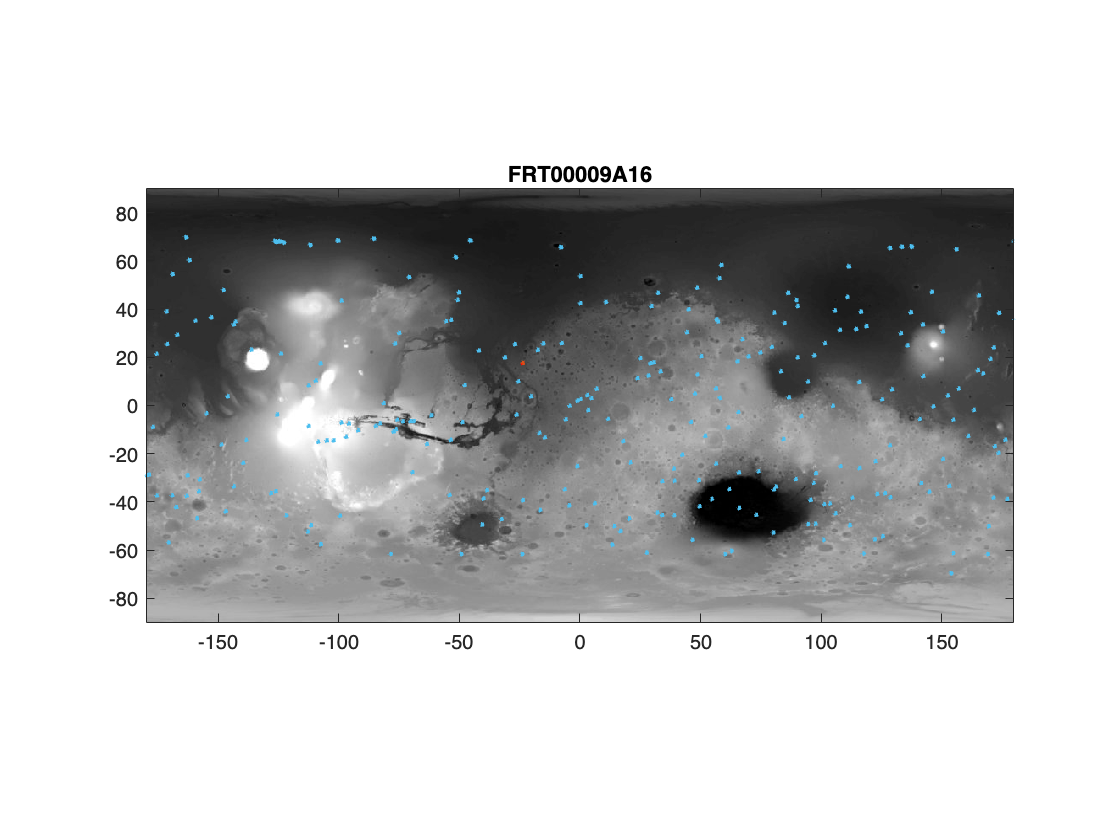

cols=lines(7);
for i=1:length(ddr_polygons_slctd)
    dirname = ddr_polygons_slctd(i).dirname;
    try
        dt = '';
        X = ddr_polygons_slctd(i).X;
        if (max(X) - min(X)) > 150
            X(X<-150) = X(X<150)+360;
        end
        Y = ddr_polygons_slctd(i).Y;
        obs_class_type = dirname(1:3);
        obs_id = dirname(4:11);
        time_i = ddr_polygons_slctd(i).time;
        c = zeros(size(X));
        dpname = sprintf('%d:%s %s_%03d',i,dirname, datestr(time_i,'yyyy'), day(time_i, 'dayofyear'));
        % fprintf('%s\n',dpname);
        if strcmpi(dirname, dirname_tar)
            edgecolor = 'r';
        else
            edgecolor = cols(6,:);
        end
        switch upper(projection_method)
            case 'EQUIRECTANGULAR'
                patch(X,Y,c, ...
                      'FaceColor',cols(1,:), 'FaceAlpha', 0, ...
                      'LineStyle', '-', 'LineWidth', 2, 'EdgeColor', edgecolor, ...
                      'DisplayName', dpname);
            case 'STEREOGRAPHIC'
                k = 2*R*cosd(Y)./(1+sind(Y));
                Xpolar = k.*cosd(X);
                Ypolar = k.*sind(X);
                Zpolar = ones(size(Xpolar));
                fill3(Xpolar,Ypolar,Zpolar,c, ...
                    'FaceColor',[1,1,1], 'FaceAlpha', 0, ...
                    'LineStyle', '-', 'LineWidth', 2, 'EdgeColor', edgecolor, ...
                    'DisplayName',dpname);
        end
    catch
        fprintf('Error processing %s\n', dirname);
    end
end

% Plot the footprint of the target image.
switch upper(projection_method)
    case 'EQUIRECTANGULAR'
        Xtar = [polygon_tar.X polygon_tar.X(1)];
        Ytar = [polygon_tar.Y polygon_tar.Y(1)]; c = zeros(size(Xtar));
        patch(Xtar,Ytar,c,'FaceColor',cols(2,:), ...
              'DisplayName',sprintf('%d:%s',i,dirname_tar), ...
              'EdgeColor',cols(2,:),'LineWidth',2);
    case 'STEREOGRAPHIC'
        Xtar = [polygon_tar.X polygon_tar.X(1)];
        Ytar = [polygon_tar.Y polygon_tar.Y(1)];
        k = 2*R*cosd(Ytar)./(1+sind(Ytar));
        Xpolar_tar = k.*cosd(Xtar);
        Ypolar_tar = k.*sind(Xtar);
        Zpolar_tar = ones(size(Xpolar_tar));
        fill3(Xpolar_tar,Ypolar_tar,Zpolar_tar,cols(6,:), ...
              'LineStyle', '-', 'LineWidth', 2, 'EdgeColor', 'r', ...
              'FaceAlpha', 0, ...
              'DisplayName', sprintf('%d:%s',i,dirname_tar));
end
set(gca,'DataAspectRatio',[1 1 1]);

## Output the list of IDs sorted by temporal proximity

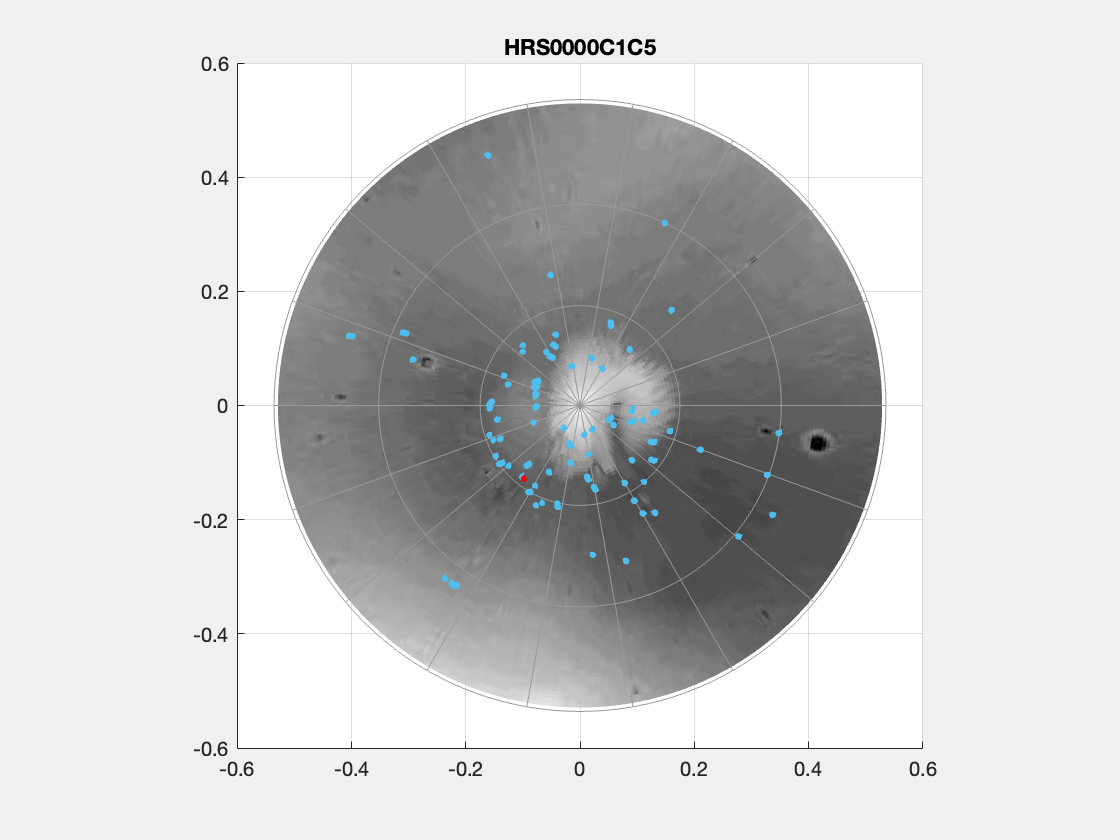

fig =   Figure (5: HRS0000C1C5) with properties:

      Number: 5
        Name: 'HRS0000C1C5'
       Color: [0.9400 0.9400 0.9400]
    Position: [584 495 560 420]
       Units: 'pixels'

  Show all properties


% dtime = abs([ddr_polygons_cand.time] - med_time_tar);
% [~,idxesrt] = sort(dtime, 'ascend');
% ddr_polygons_cand_srtd = ddr_polygons_cand(idxesrt);

filename = sprintf('%s_bland_image_candidates_lat_gt60', dirname_tar);
save([filename '.mat'], 'ddr_polygons_slctd', 'polygon_tar');
fig.Visible = 'on'

savefig(fig, [filename '.fig']);



% Print the list
for i=1:length(ddr_polygons_slctd)
    dirname_i = ddr_polygons_slctd(i).dirname;
    time_i = ddr_polygons_slctd(i).time;
    if strcmpi(dirname_i, dirname_tar)
        fprintf('X% 3d: %s_%03d: %s\n',i, datestr(time_i,'yyyy'), day(time_i, 'dayofyear'), dirname_i);
    else
        fprintf('% 4d: %s_%03d: %s\n',i, datestr(time_i,'yyyy'), day(time_i, 'dayofyear'), dirname_i);
    end
end